线性方程形式要求：

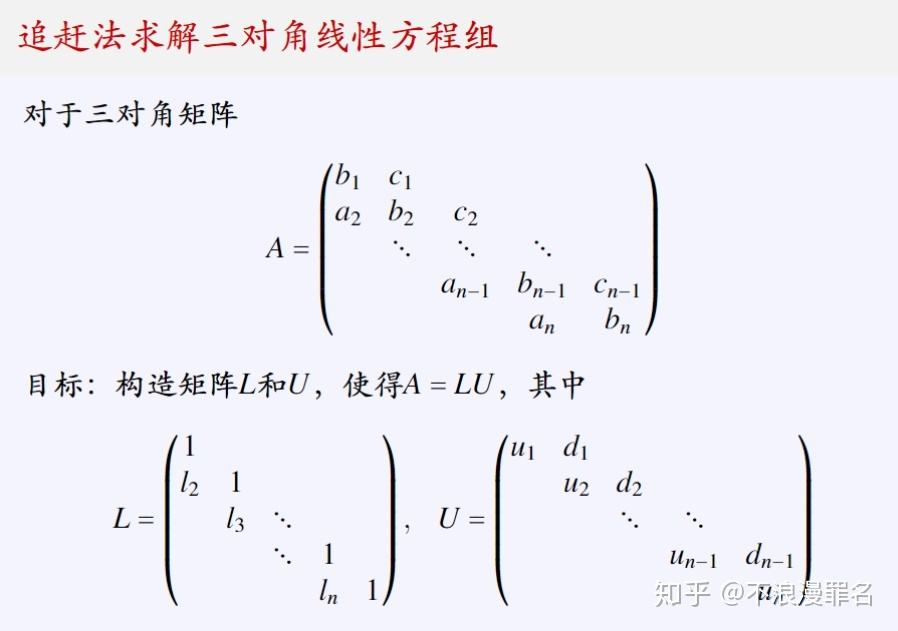

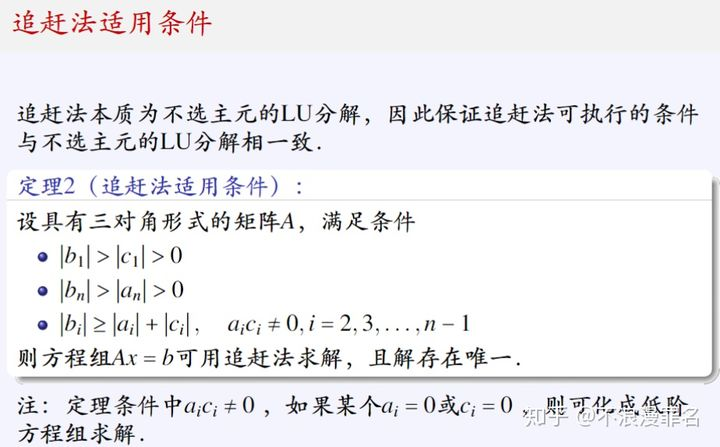

clc,clear,close all

A = [3 1 0 0 
    1 4 1 0
    0 1 6 1
    0 0 2 8];

f = [10
    11
    30
    48];

n = length(f);


完成 LU 分解

b = diag(A);
c = diag(A,1);
a = diag(A,-1);
alpha = zeros(1,n);
beta = zeros(1,n-1);
r = a;
alpha(1) = b(1);
beta(1) = c(1)/alpha(1);
for i = 2:n-1
    alpha(i) = b(i)-a(i-1)*beta(i-1);
    beta(i) = c(i)/alpha(i);
end
alpha(n) =b(n)-a(n-1)*beta(n-1);
L = diag(alpha);
L = L+diag(r,-1);
U = diag(ones(1,n))+diag(beta,1);
disp('L 为')

L 为


disp(L)

       3              0              0              0       
       1             11/3            0              0       
       0              1             63/11           0       
       0              0              2            482/63    



disp('U 为')

U 为


disp(U)

       1              1/3            0              0       
       0              1              3/11           0       
       0              0              1             11/63    
       0              0              0              1       



解 $Ly=f$

y = zeros(n,1);
y(1) = f(1)/alpha(1);

for i = 2:n
    y(i) = (f(i) - r(i-1)*y(i-1))/alpha(i);
end




解 Ux = y

x = zeros(n,1);
x(n) = y(n);

for i = n-1:-1:1
    x(i) = y(i)-beta(i)*x(i+1);
end




disp('真实解为')

真实解为


disp(A\f)

       3       
       1       
       4       
       5       



disp('追赶法求得的解为')

追赶法求得的解为


disp(x)

       3       
       1       
       4       
       5       

